%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to perform high pass filtering
%----------------------------------------------------------------------

close all;
clear all;
clc;

filename = ('/Users/sumitpatidar/Desktop/input_audio.m4a');
%read a audio file
[y, Fs] = audioread(filename);
N = Fs;
samples = [1, N];
[y1, Fs] = audioread(filename , samples);

filename_in = '/Users/sumitpatidar/Desktop/audio_in2.wav'

filename_in = '/Users/sumitpatidar/Desktop/audio_in2.wav'

audiowrite(filename_in, y1, Fs);
%sound(y1, N);

%DFT of the input sound signal
X_in = dft_user(y1, N);

%plot DFT of input signal
p1 = subplot(3,1,1);
stem([0:N-1], abs(X_in));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT X[k]');
hold on;

%----------------------------------------High pass filtering begin-------------------------
%DFT of high pass filter signal
wp = pi/2;
X_hp = zeros(1, N);
for k = 0:N-1
    if ((2*pi*k/N) >= wp && ((2*pi*k/N)) <= (2*pi - wp))
        X_hp(k+1) = 1;
    else 
        X_hp(k+1) = 0;
    end
end

%multiply the two signals
Y_hp = X_hp.*X_in;

%take idft to convert it back to time domain
y_out_hp = idft_user(Y_hp, N);
y_hp = abs(y_out_hp);

filename_out_hp = '/Users/sumitpatidar/Desktop/audio_hp2.wav'

filename_out_hp = '/Users/sumitpatidar/Desktop/audio_hp2.wav'

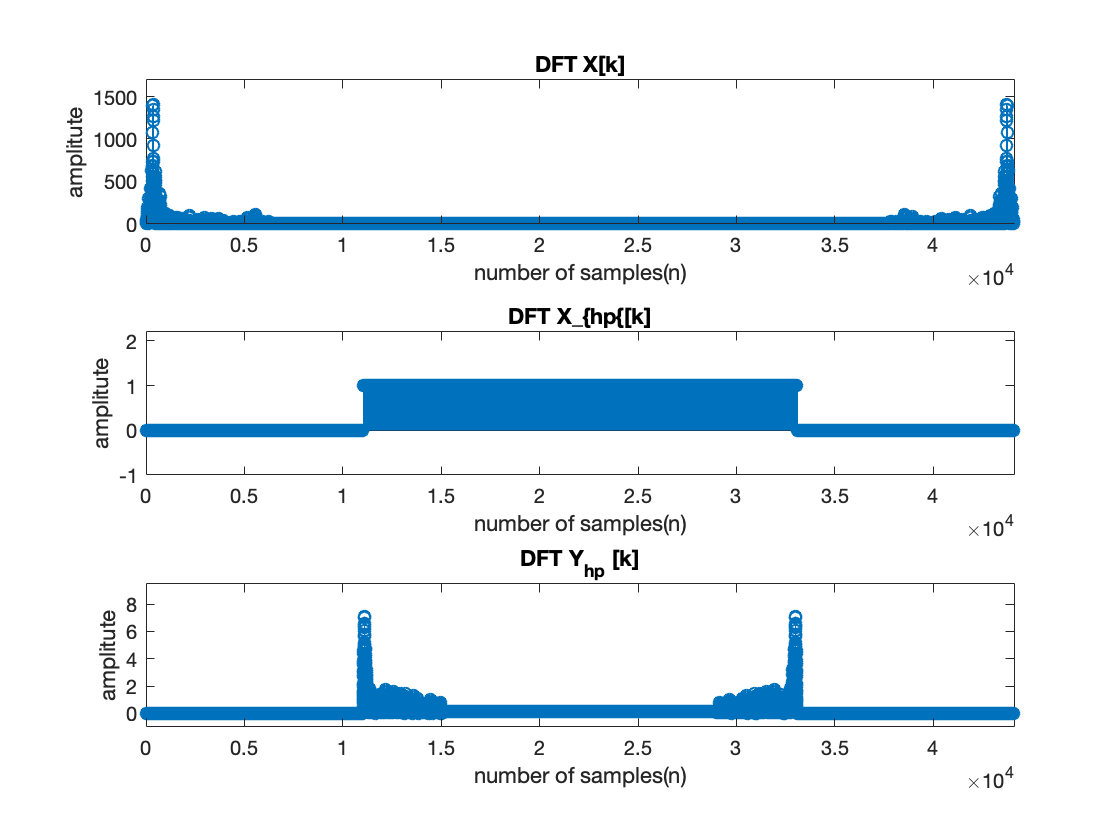

audiowrite(filename_out_hp, y_hp, Fs);

%plot DFT of input signal
p2 = subplot(3,1,2);
stem([0:N-1], abs(X_hp));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT X_{hp{[k]');
hold on;

%plot DFT of input signal
p3 = subplot(3,1,3);
stem([0:N-1], abs(Y_hp));
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT Y_{hp} [k]');
hold on;

%sound(y_hp, Fs);
%----------------------------------------High pass filtering end-------------------------

%setting axis limits to visualize better
axis(p1, [-1  N min(abs(X_in))*1.2-1 max(abs(X_in))*1.2+1]);
axis(p2, [-1  N min(abs(X_hp))*1.2-1 max(abs(X_hp))*1.2+1]);
axis(p3, [-1  N min(abs(Y_hp))*1.2-1 max(abs(Y_hp))*1.2+1]);